clc;
which myfft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myfft.m


which myifft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myifft.m


%setup for N and x_n
N = 6;
n = 0:1:N-1;
x_n = transpose(cos((pi/3).*n))

x_n =     1.0000
    0.5000
   -0.5000
   -1.0000
   -0.5000
    0.5000


%find fourier transform
X_k = myfft(x_n)

X_k =   -0.0000 + 0.0000i
   3.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   3.0000 + 0.0000i


X_K_Checking = fft(x_n)

X_K_Checking =   -0.0000 + 0.0000i
   3.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.0000 + 0.0000i


X_k_ifft = myifft(X_k)

X_k_ifft =    1.0000 + 0.0000i
   0.5000 + 0.0000i
  -0.5000 + 0.0000i
  -1.0000 + 0.0000i
  -0.5000 + 0.0000i
   0.5000 + 0.0000i


error = sum(real(x_n - X_k_ifft)) %e-15 error need to check if thats acceptable

error = -1.2768e-15

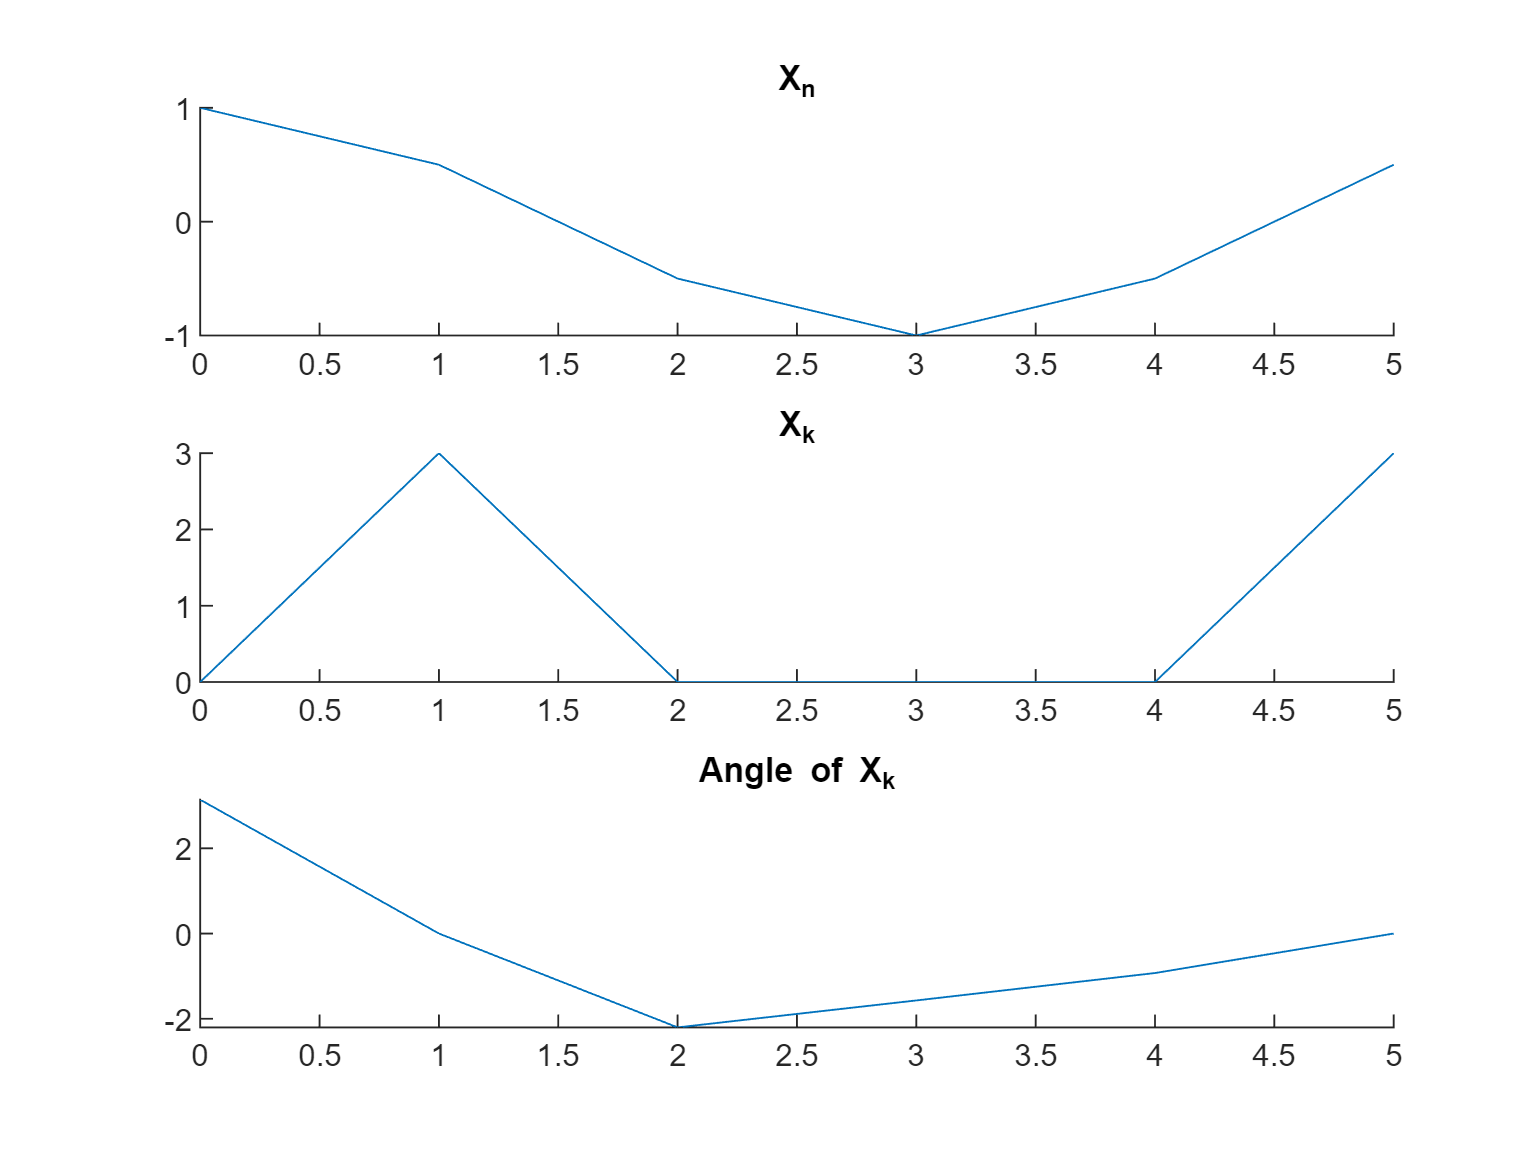

figure(1)
subplot(3,1,1)
hold on
plot(n,x_n)
title("X_n")

subplot(3,1,2);
hold on
title('X_k');
plot(n,abs(X_k));
subplot(3,1,3);
hold on
title('Angle of X_k')
plot(n,angle(X_k));

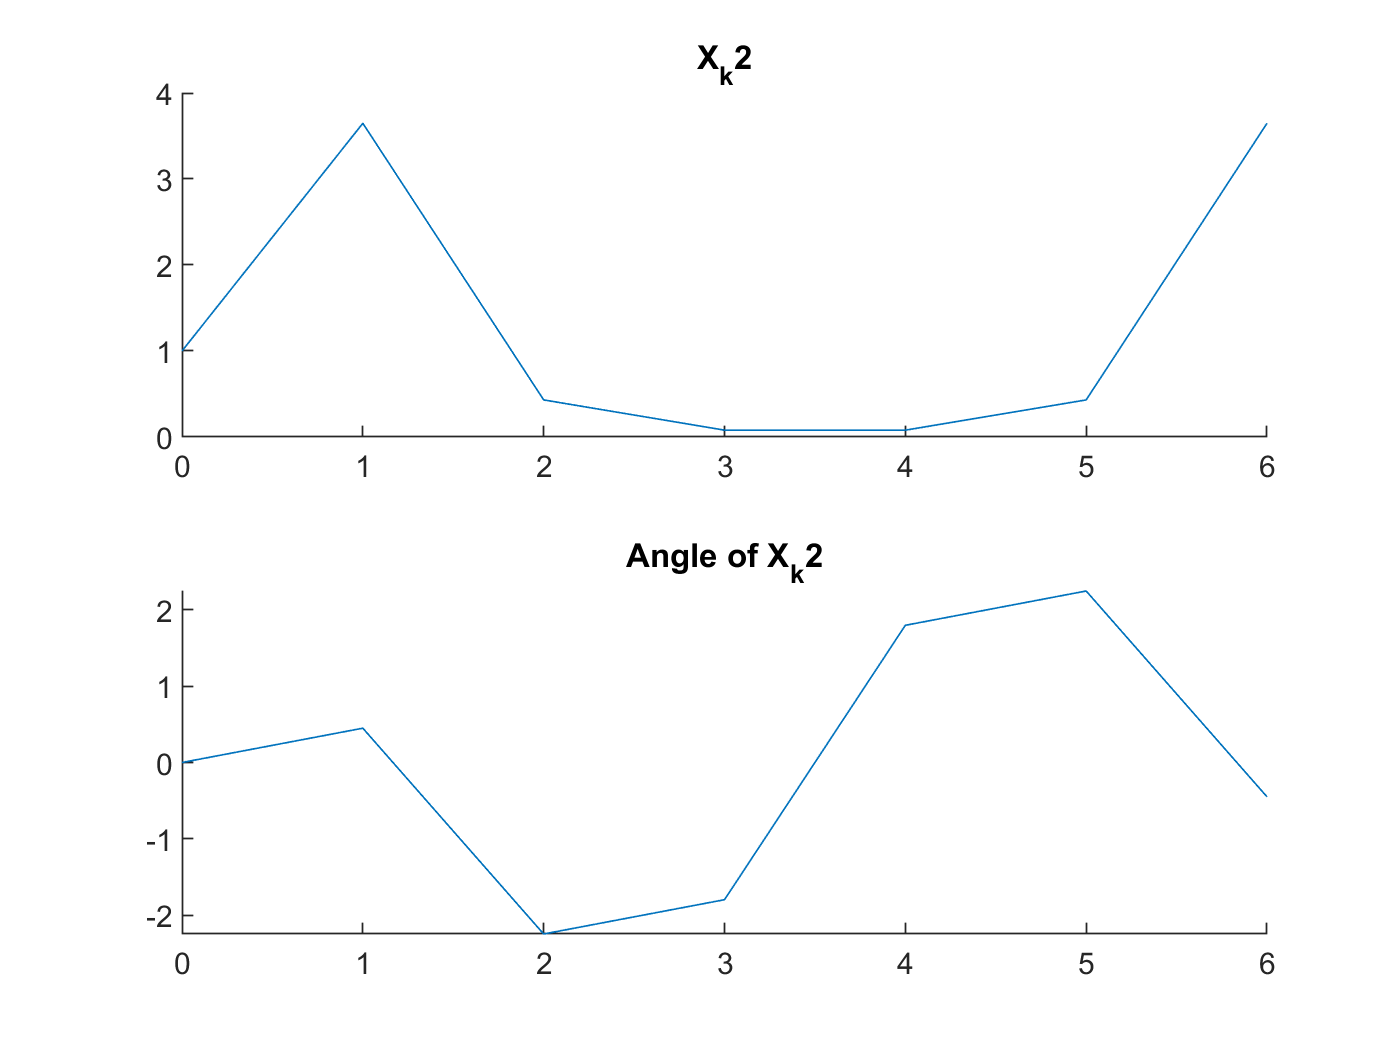

N=7;
n = 0:1:N-1;

x_n2 = transpose(cos((pi/3).*n));

x_k2 = myfft(x_n2);

figure(2)
subplot(2,1,1);
hold on
title('X_k2');
plot(n,abs(x_k2));

subplot(2,1,2);
hold on
title('Angle of X_k2')
plot(n,angle(x_k2));

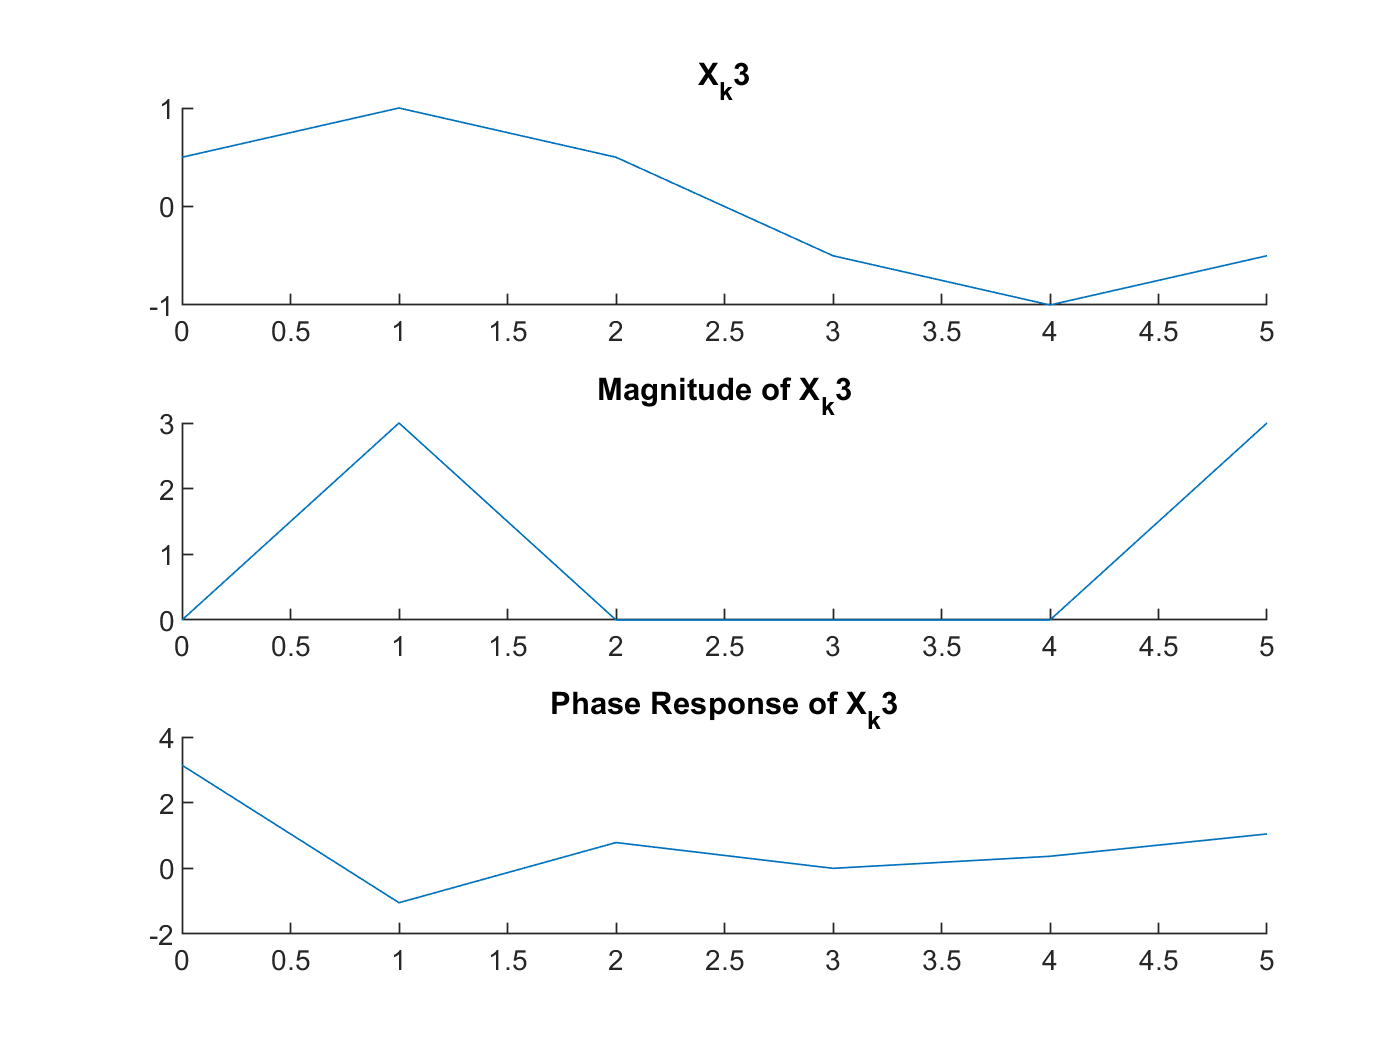

N=6; %Phase shifted
n = 0:1:N-1;

x_n3 = transpose(cos((pi/3).*(n-1)));

x_k3 = myfft(x_n3);

figure(3)
subplot(3,1,1);
hold on
title('X_k3');
plot(n,x_n3);
subplot(3,1,2);
hold on
title('Magnitude of X_k3')
plot(n,abs(x_k3));

subplot(3,1,3);
hold on
title('Phase Response of X_k3')
plot(n,angle(x_k3));

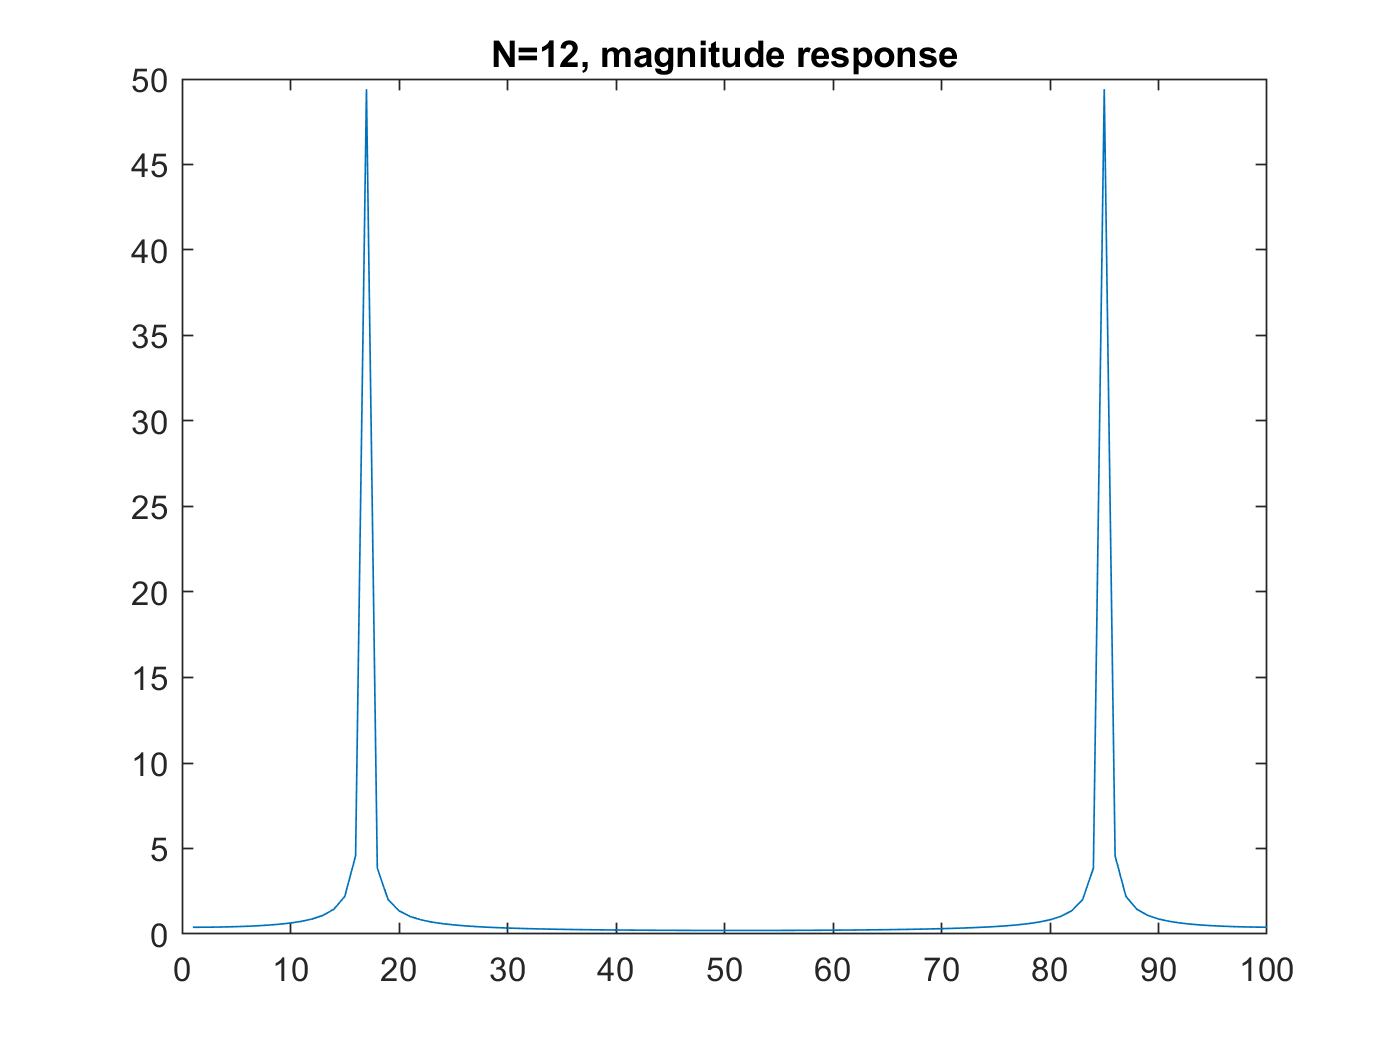

N=100;
n = 0:1:N-1;
x_n4 = cos(n);
x_k4 = myfft(transpose(x_n4));
figure(5);
plot(abs(x_k4));
title("N=12, magnitude response")
hold off

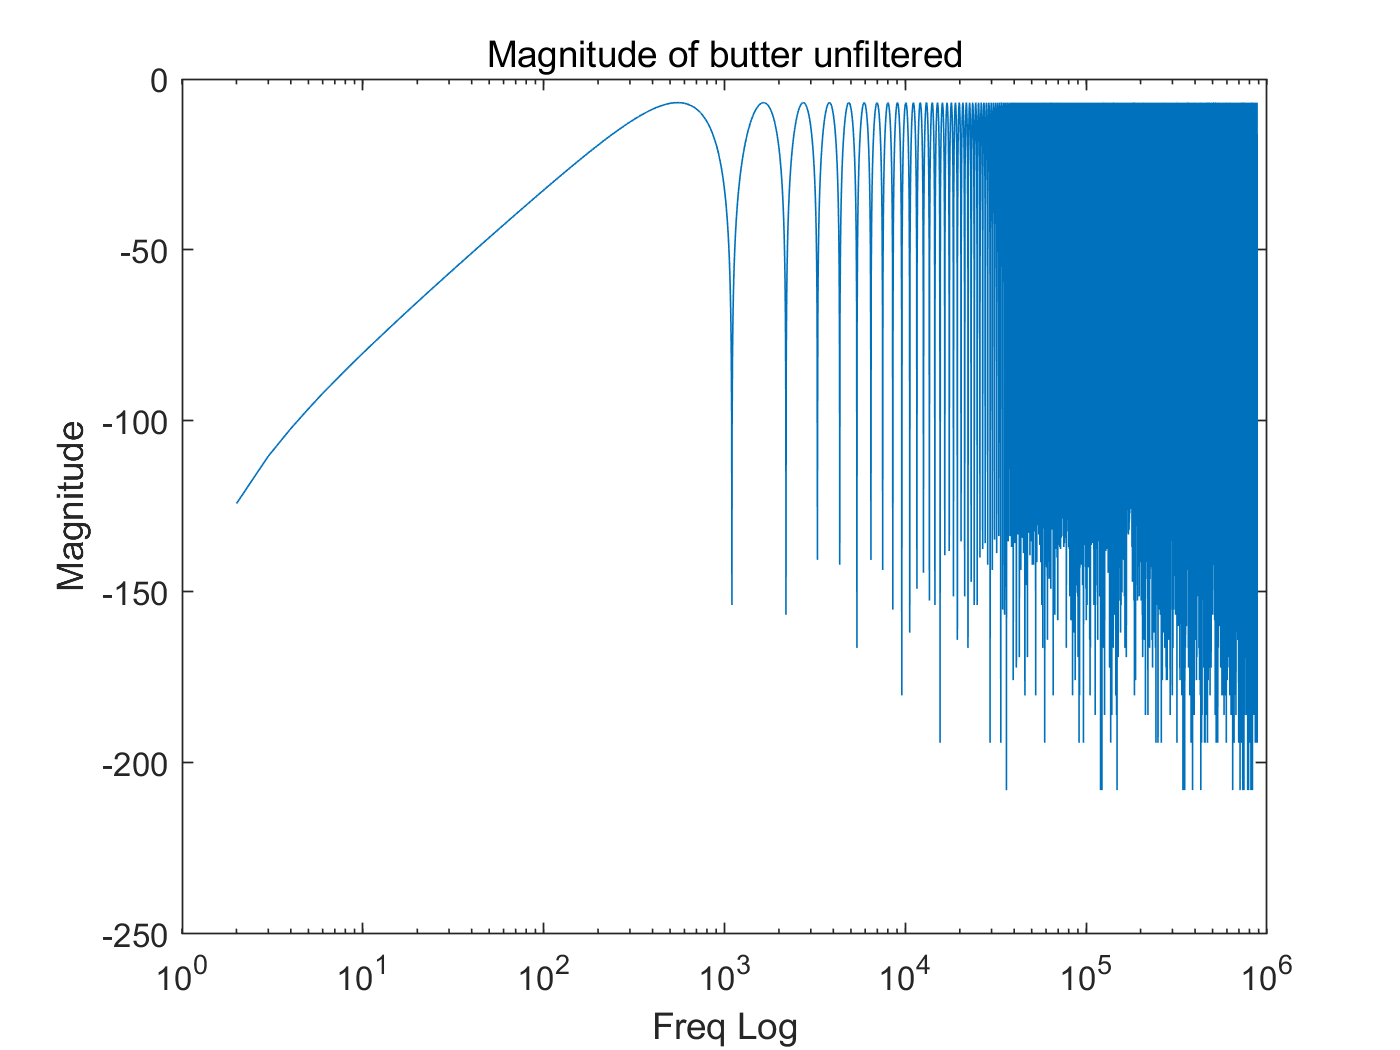

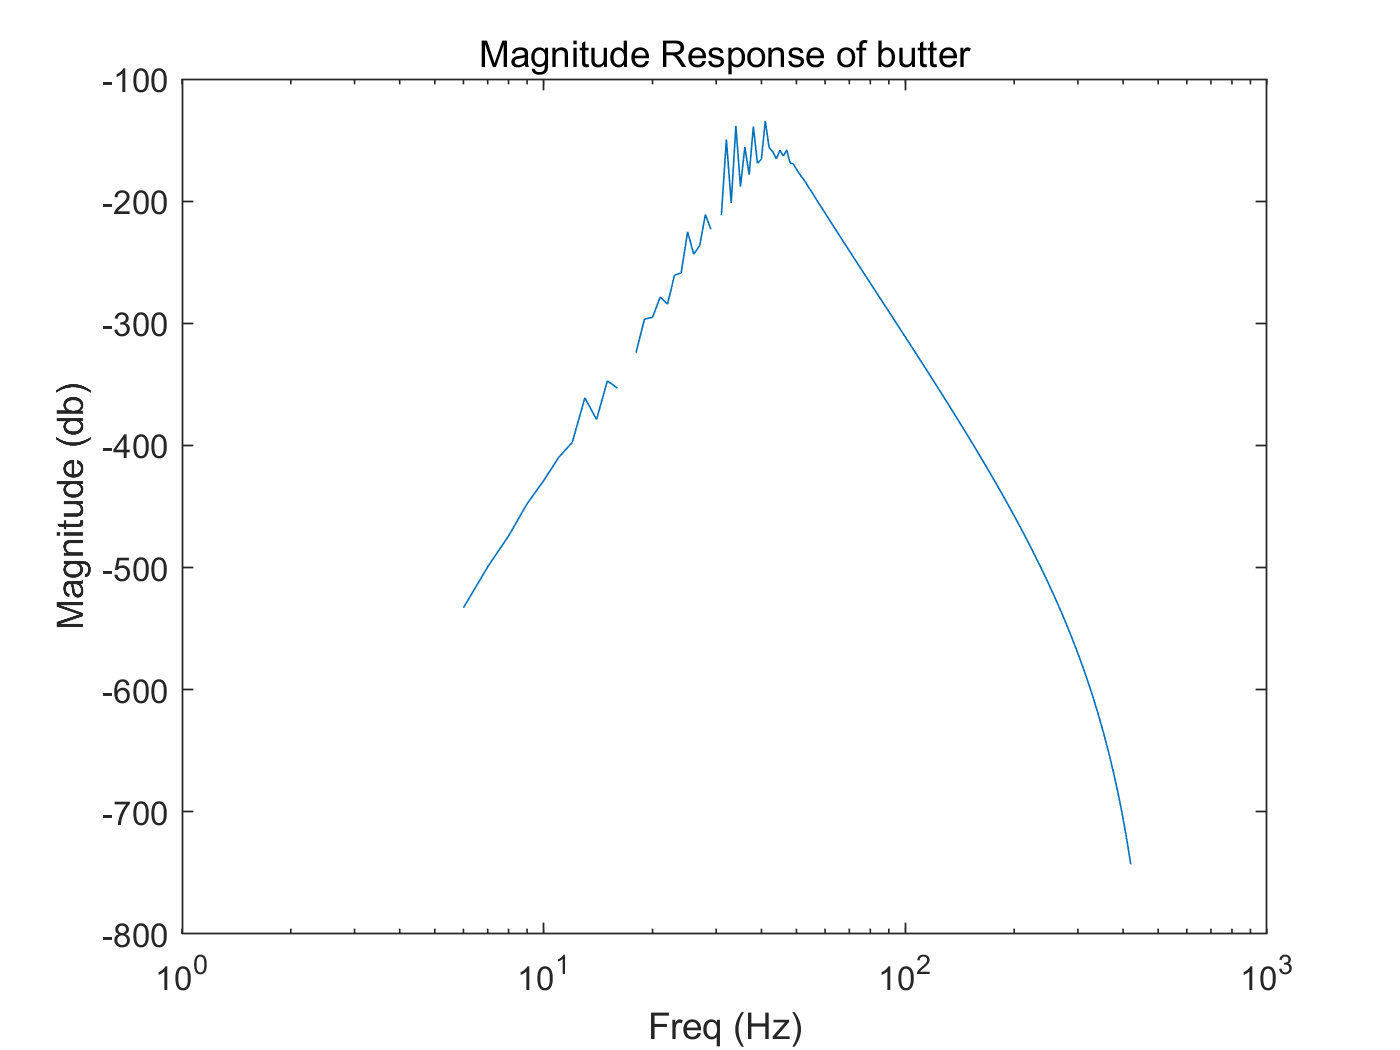

iir(SOS_butter, G_butter,"butter") %butterworth

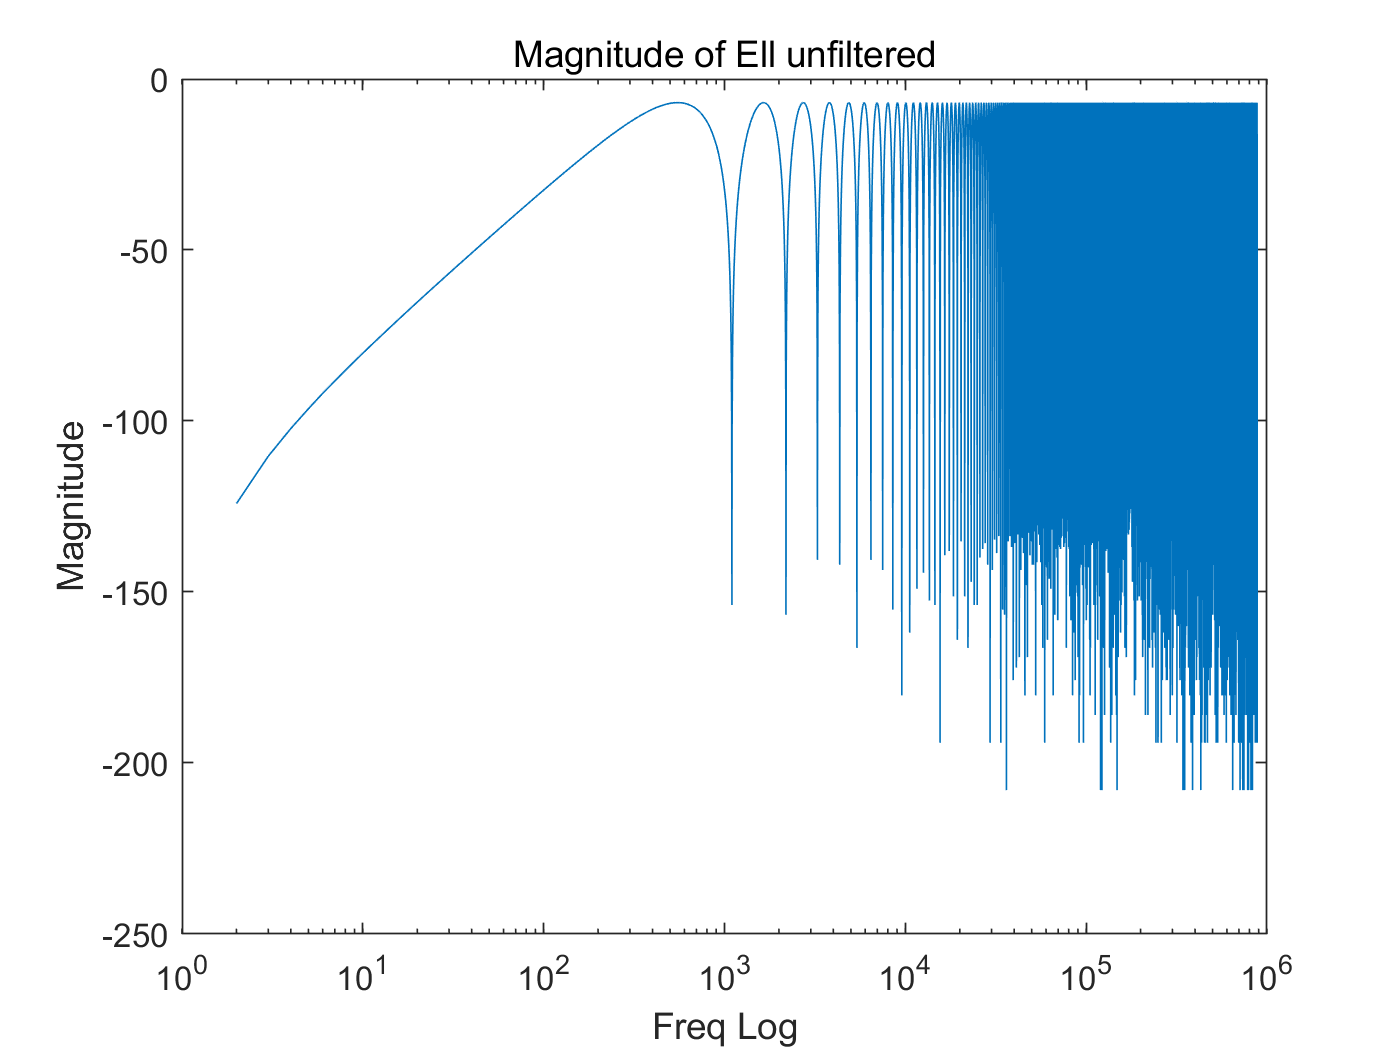

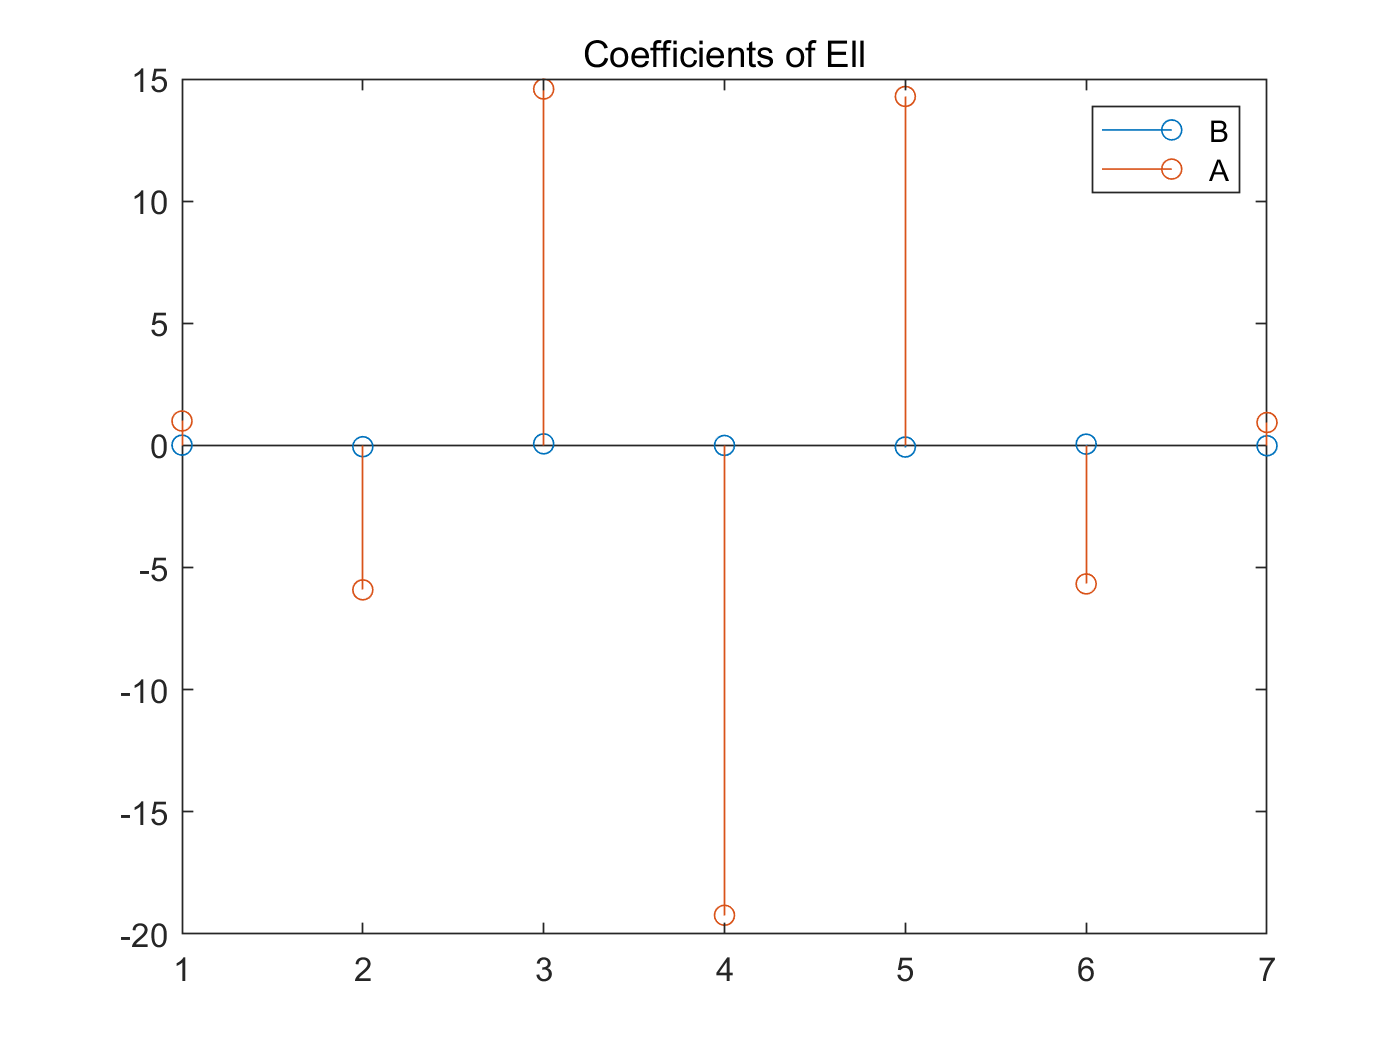

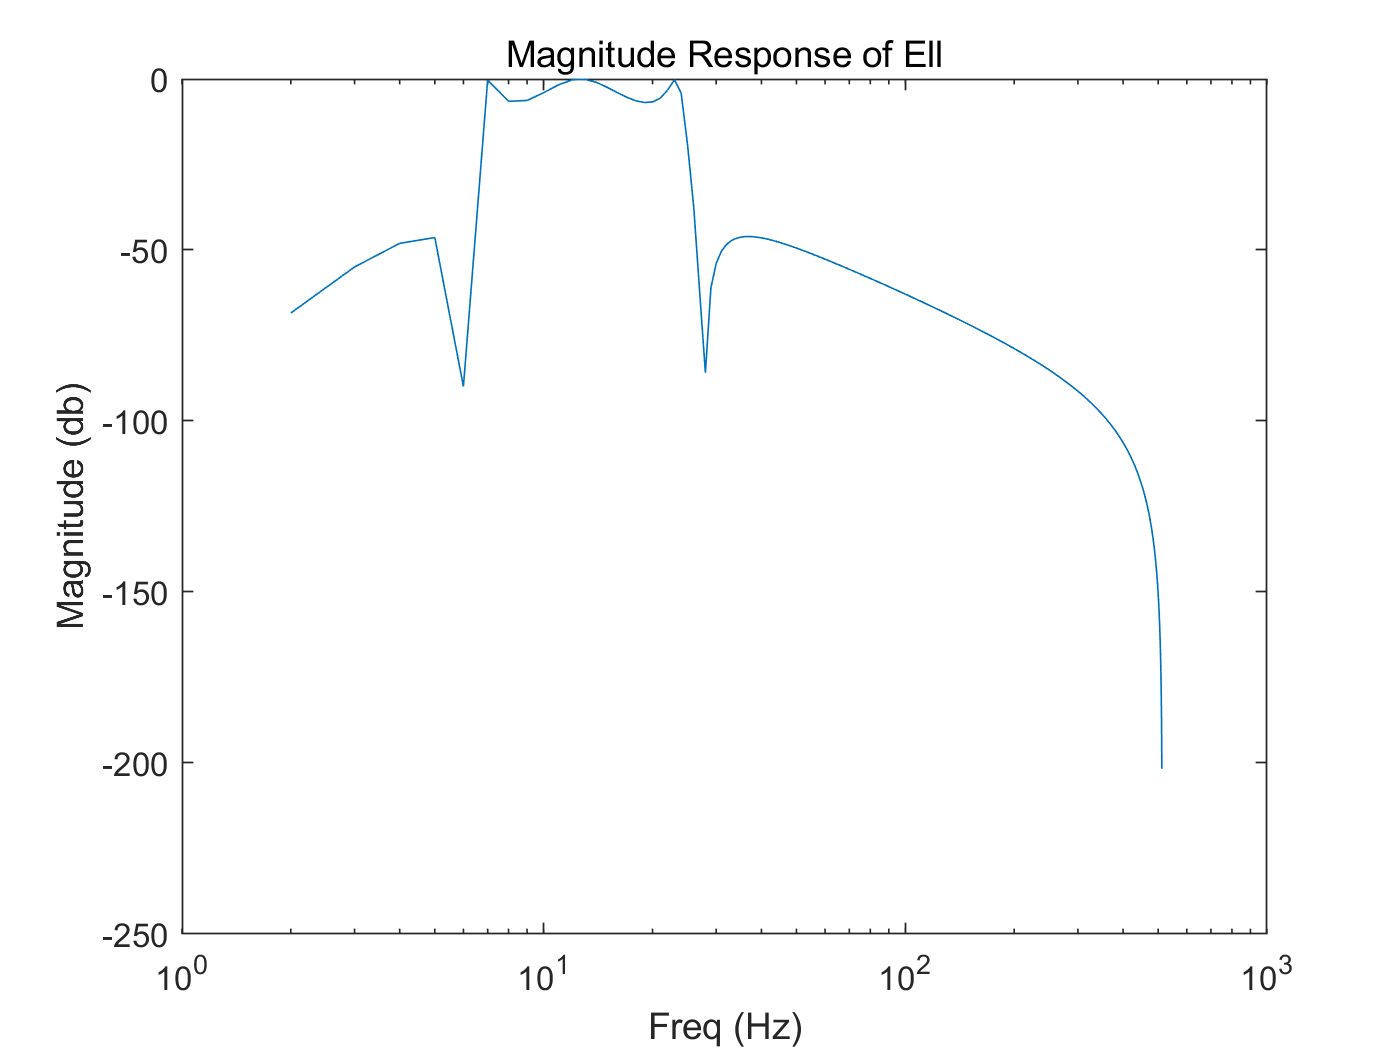

iir(SOS_Ell,G_Ell,"Ell");

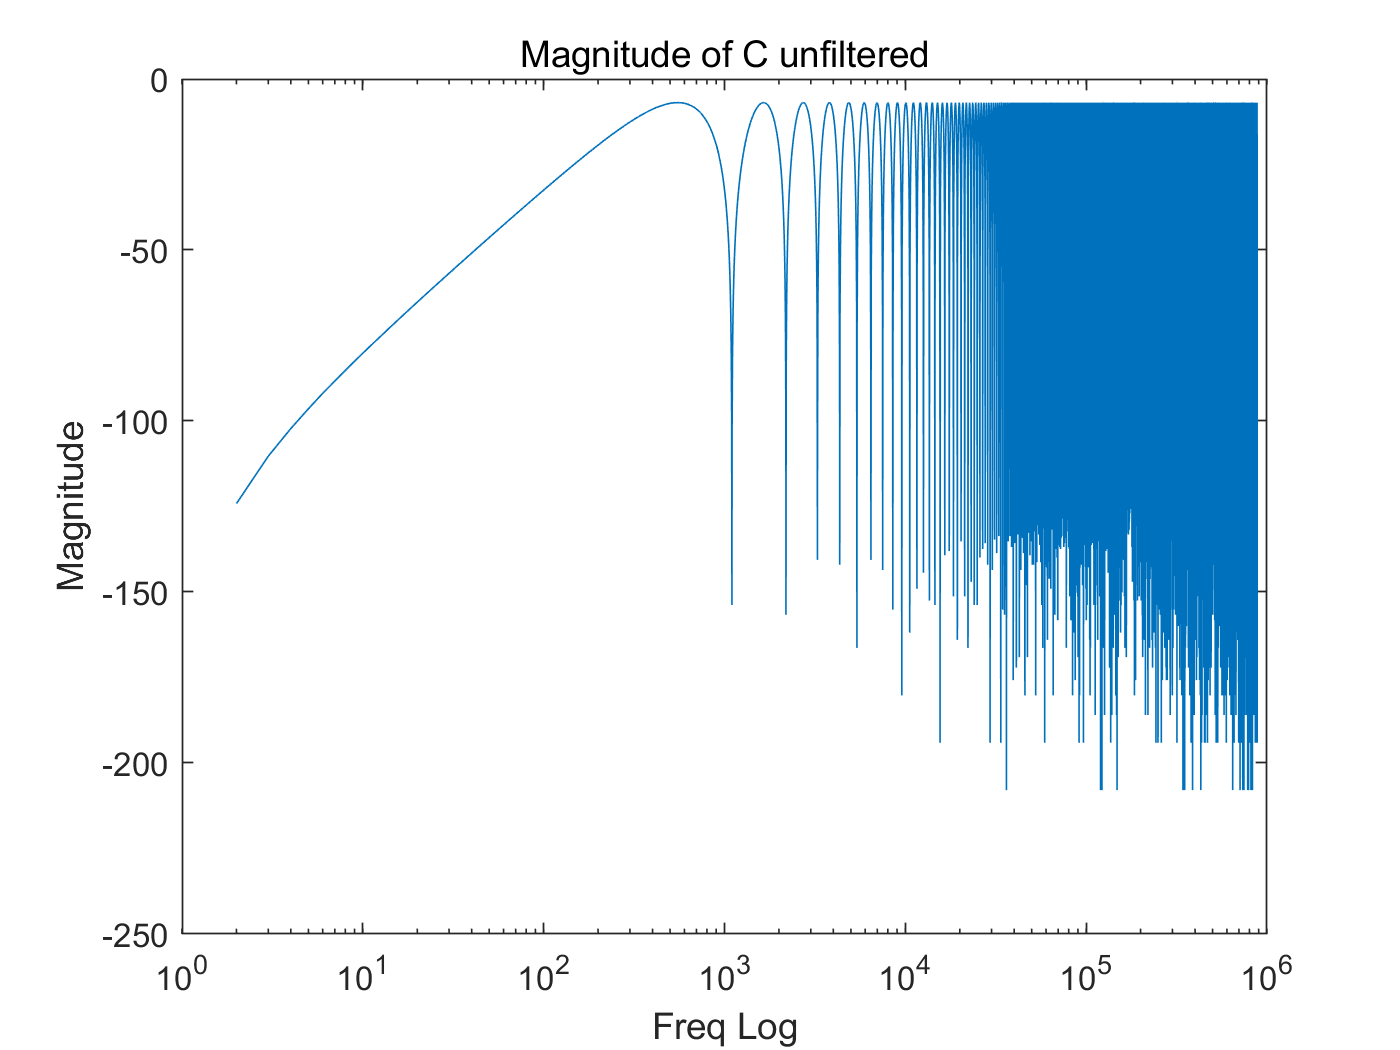

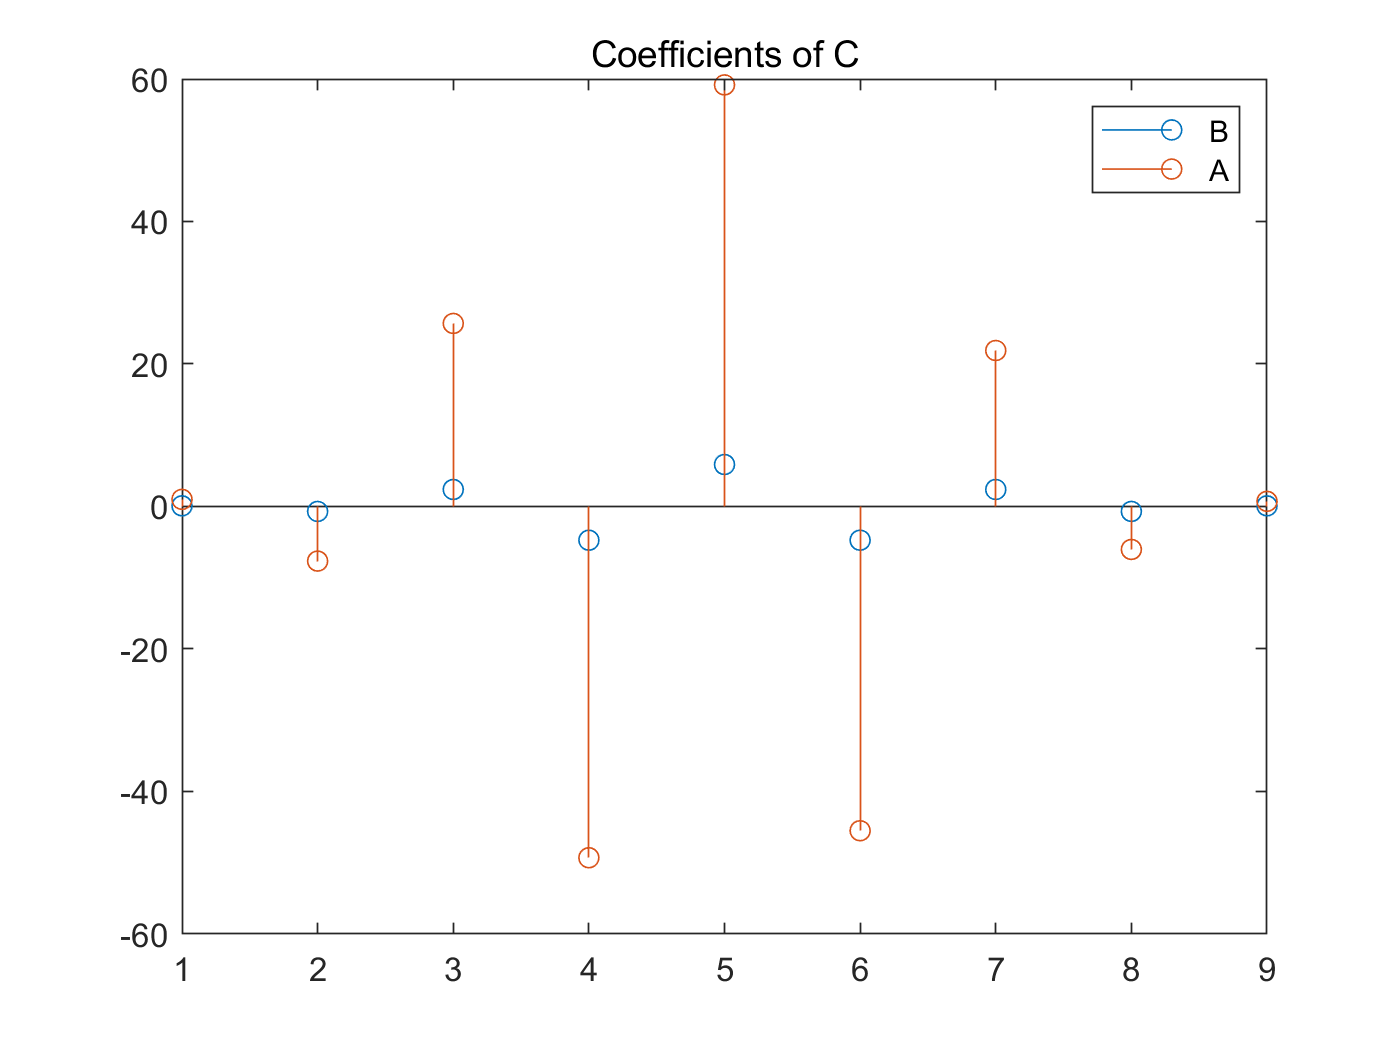

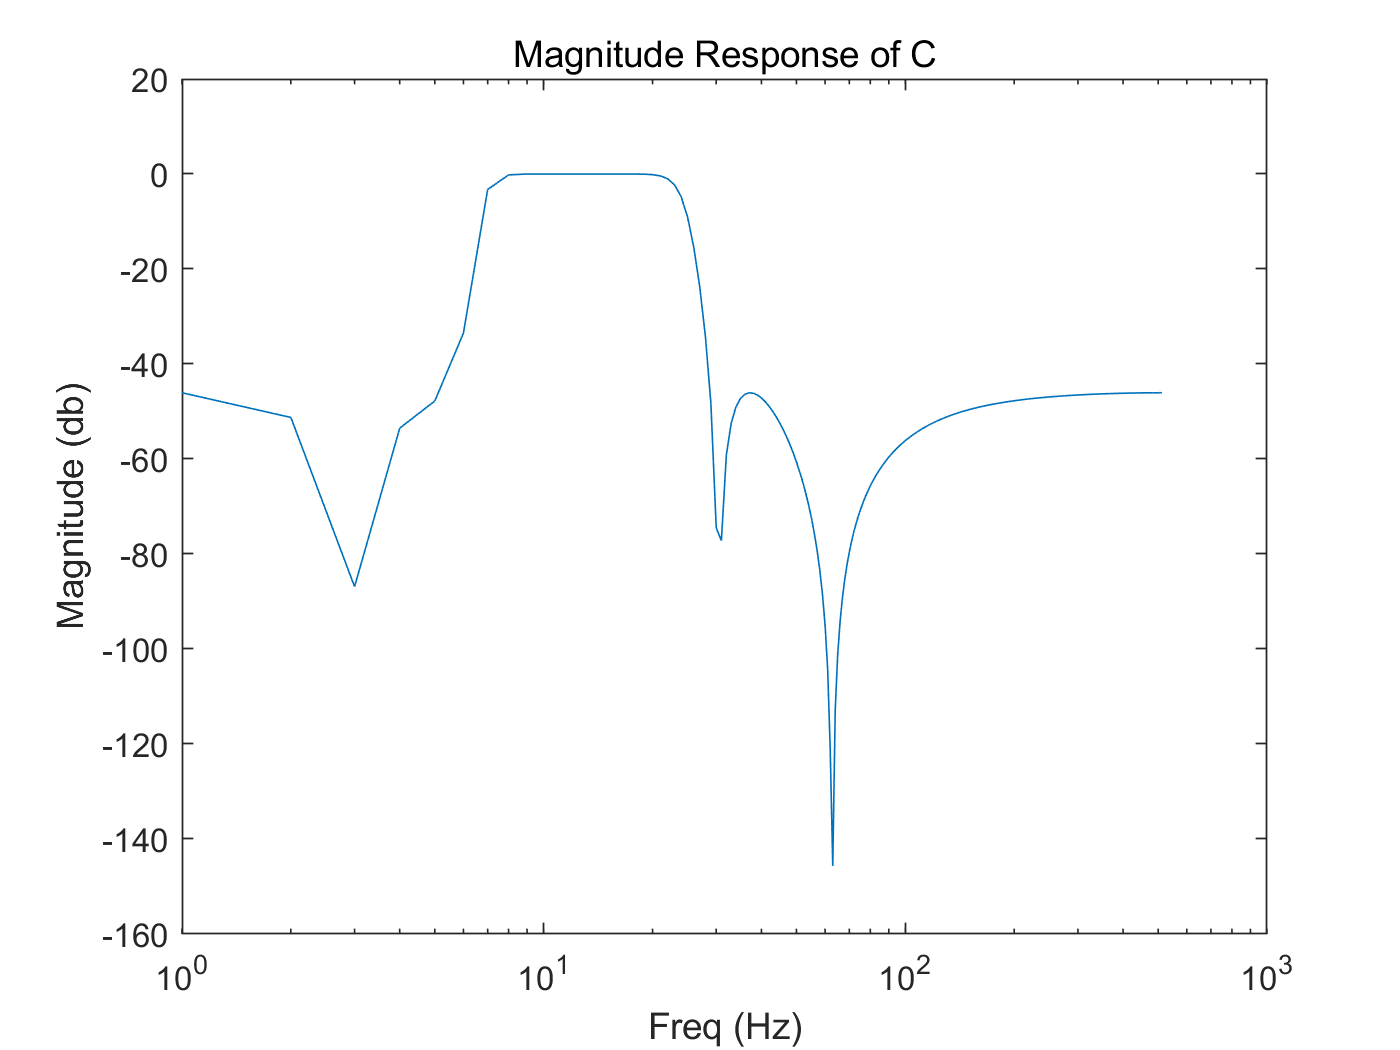

iir(SOS_C,G_C,"C")

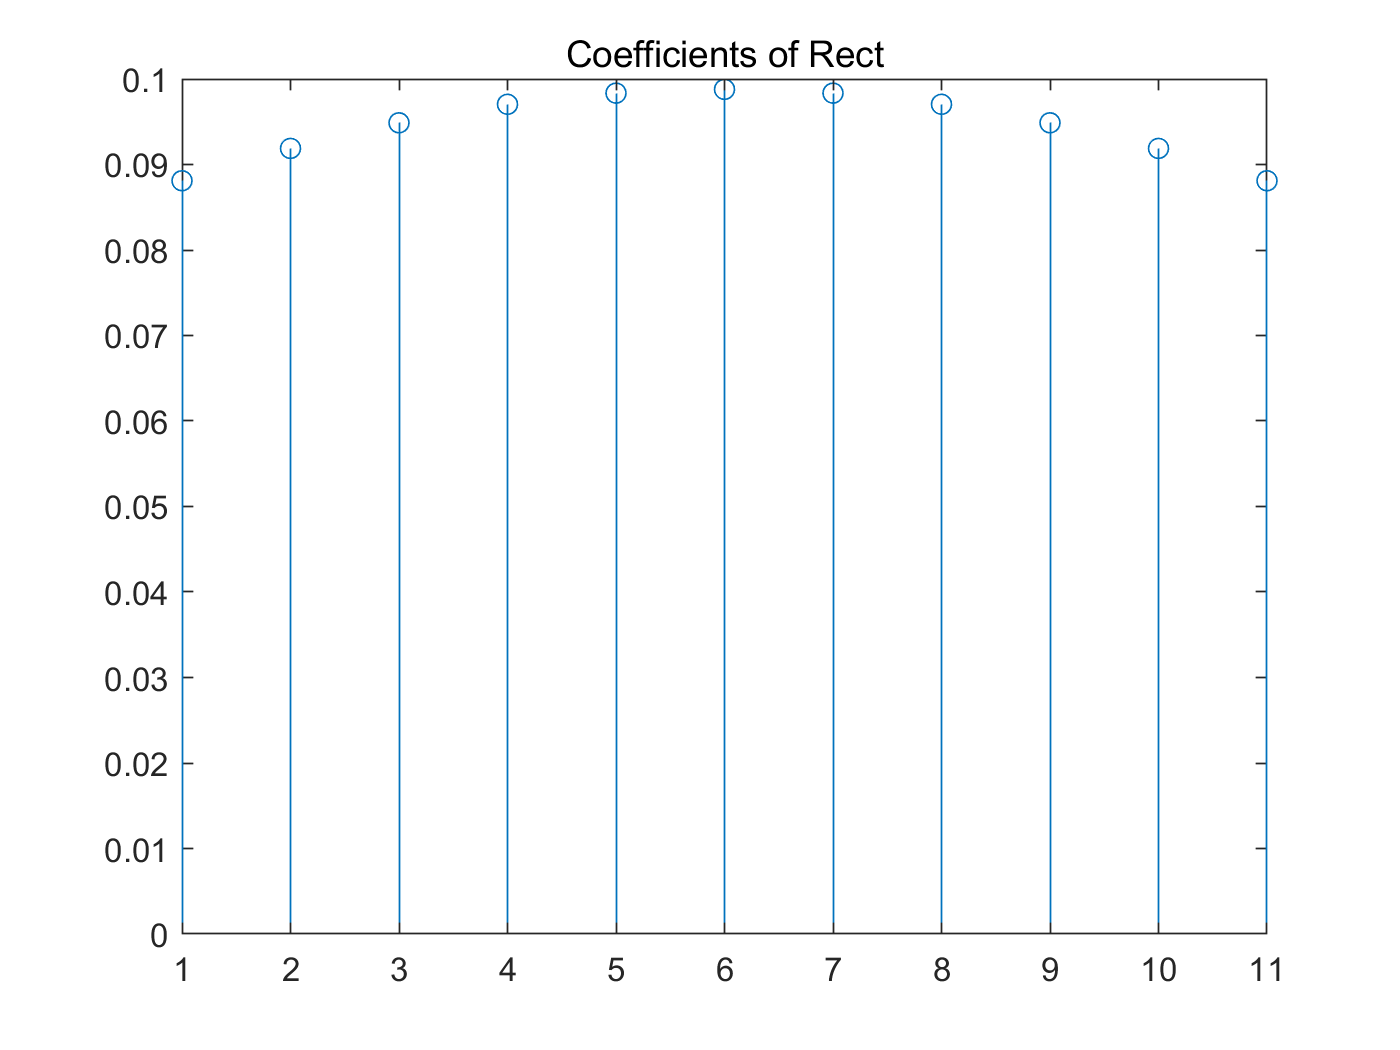

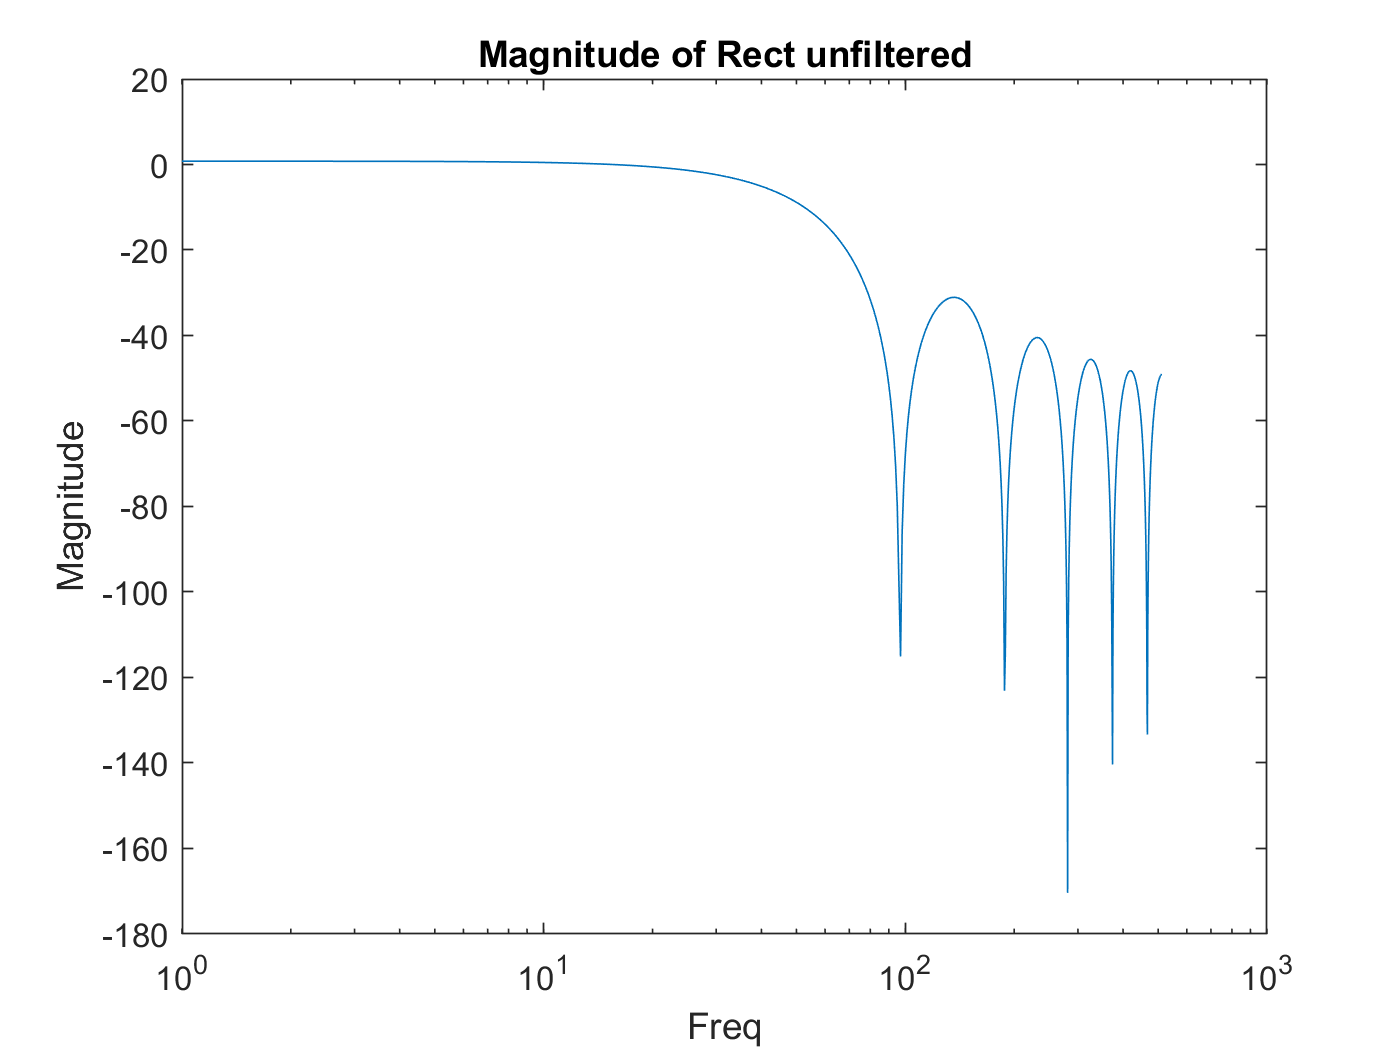

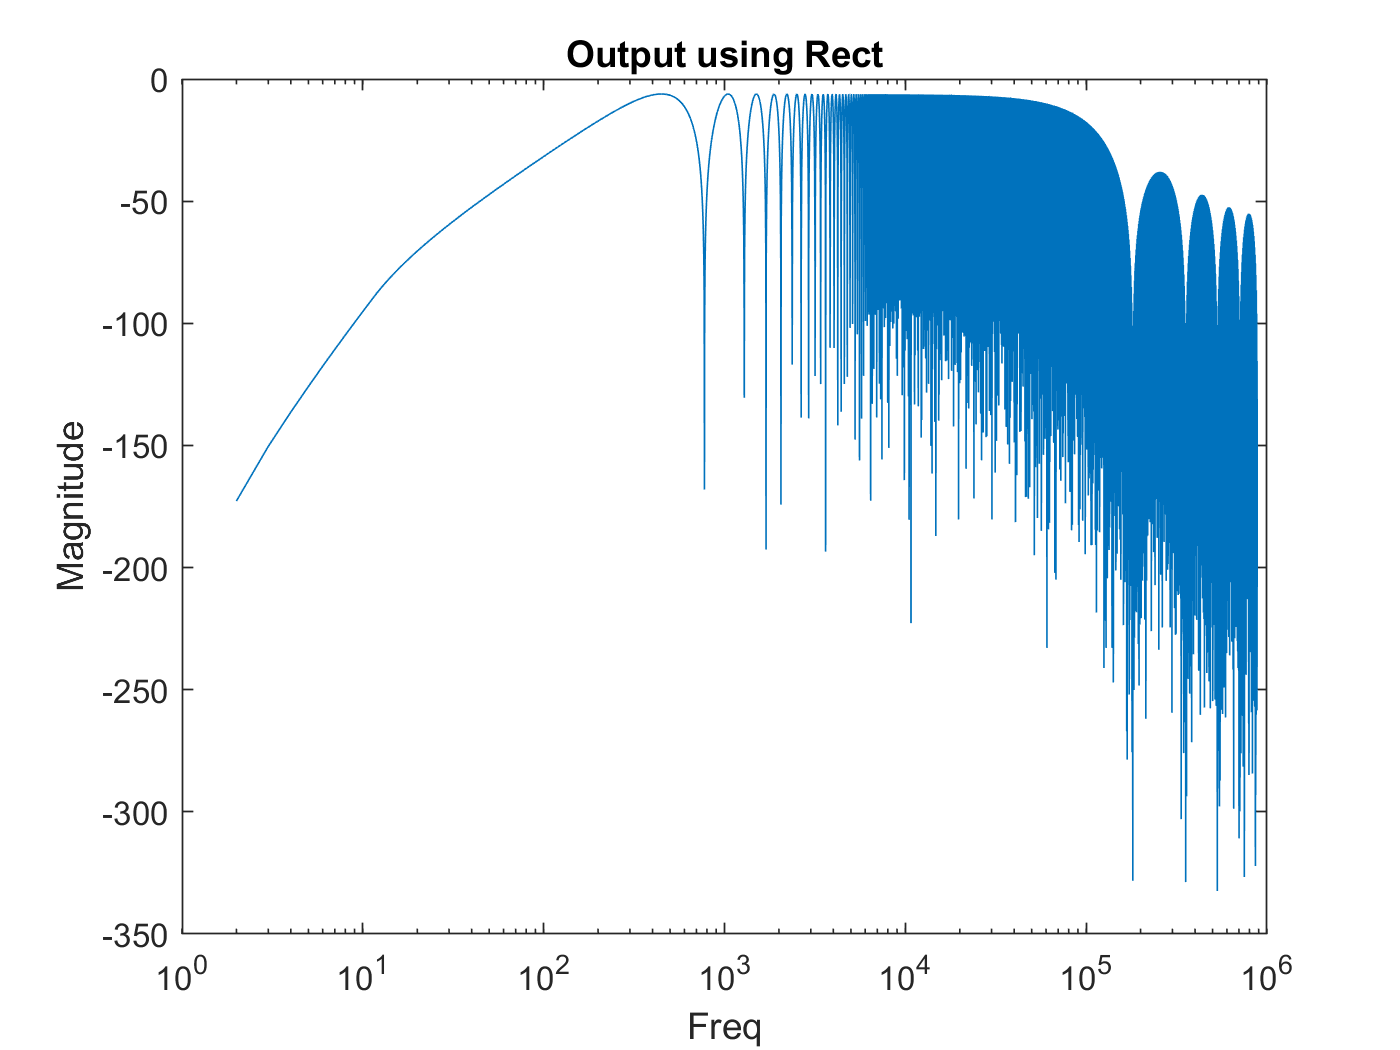

fir(B_Rect,"Rect")

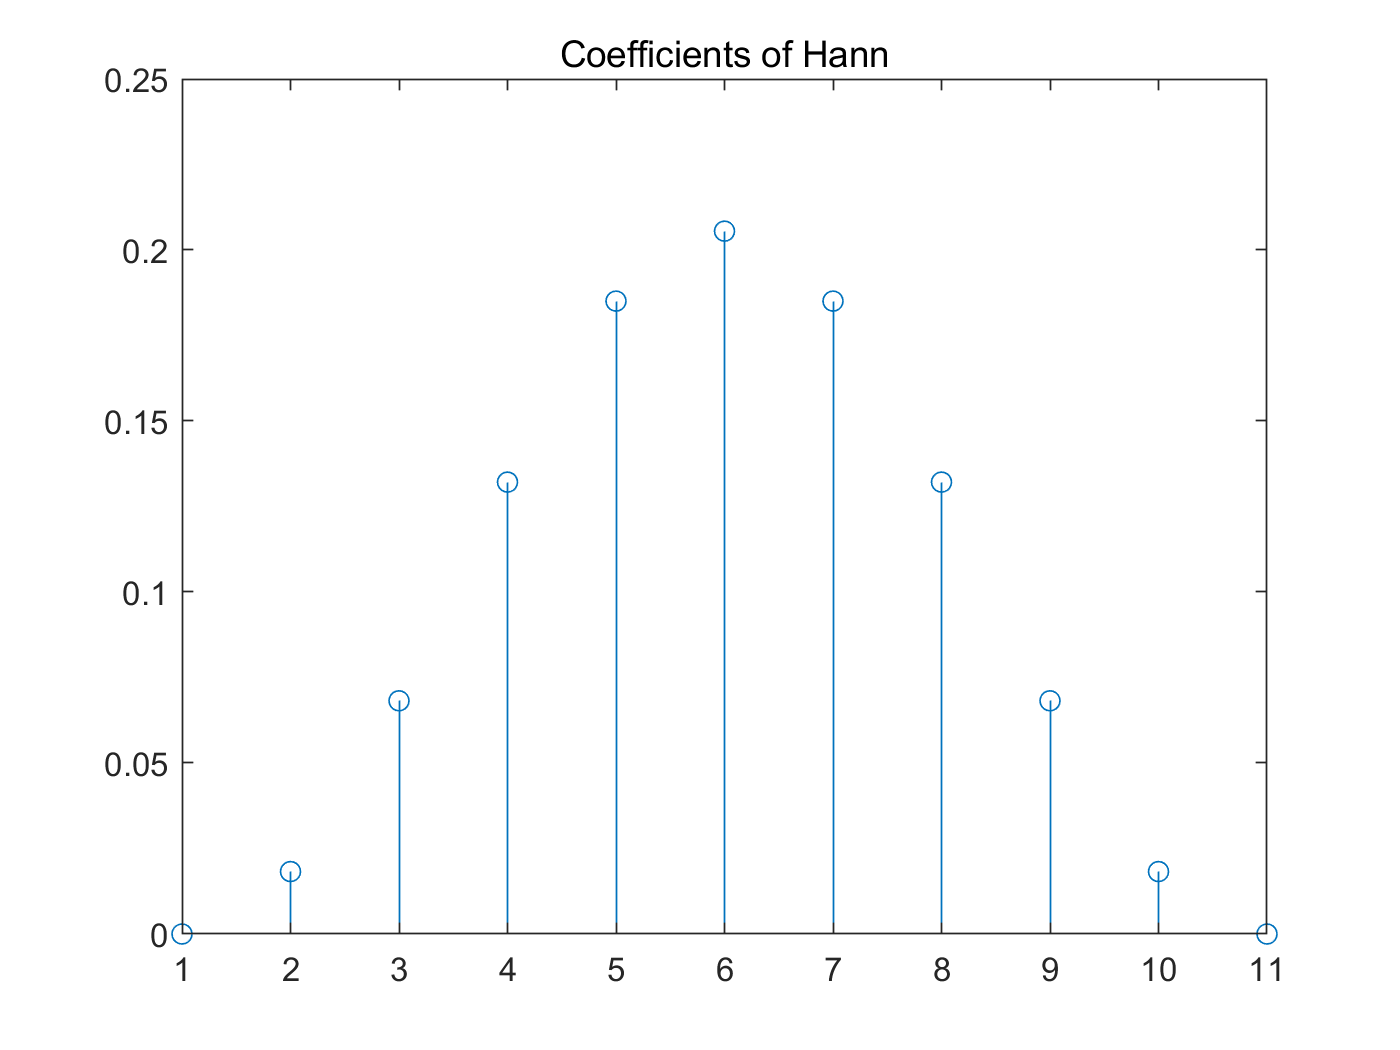

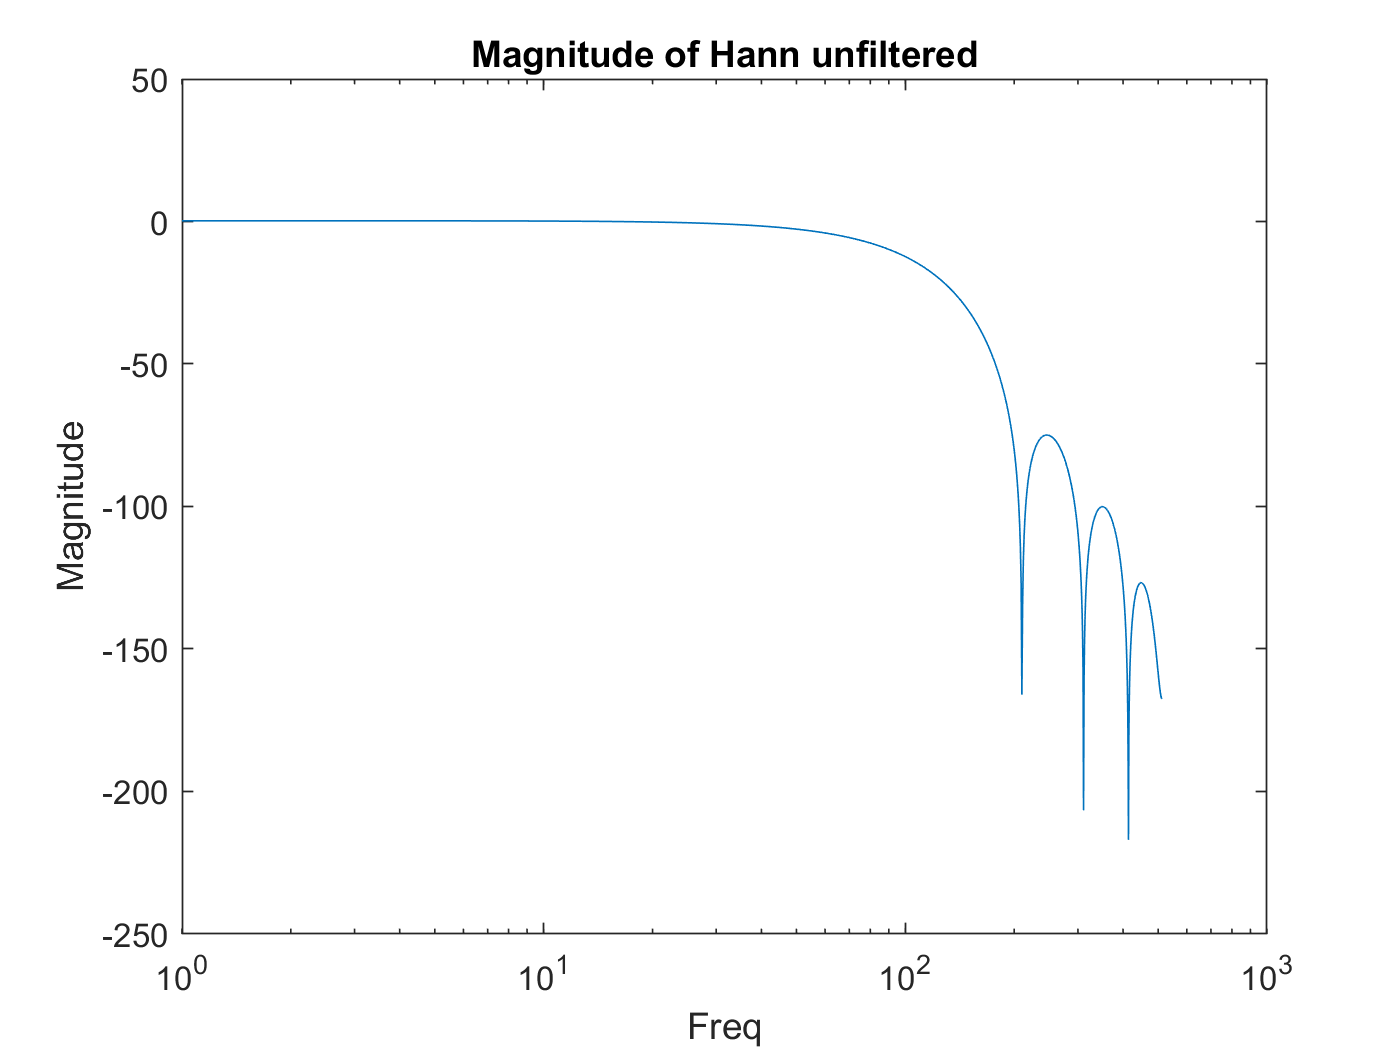

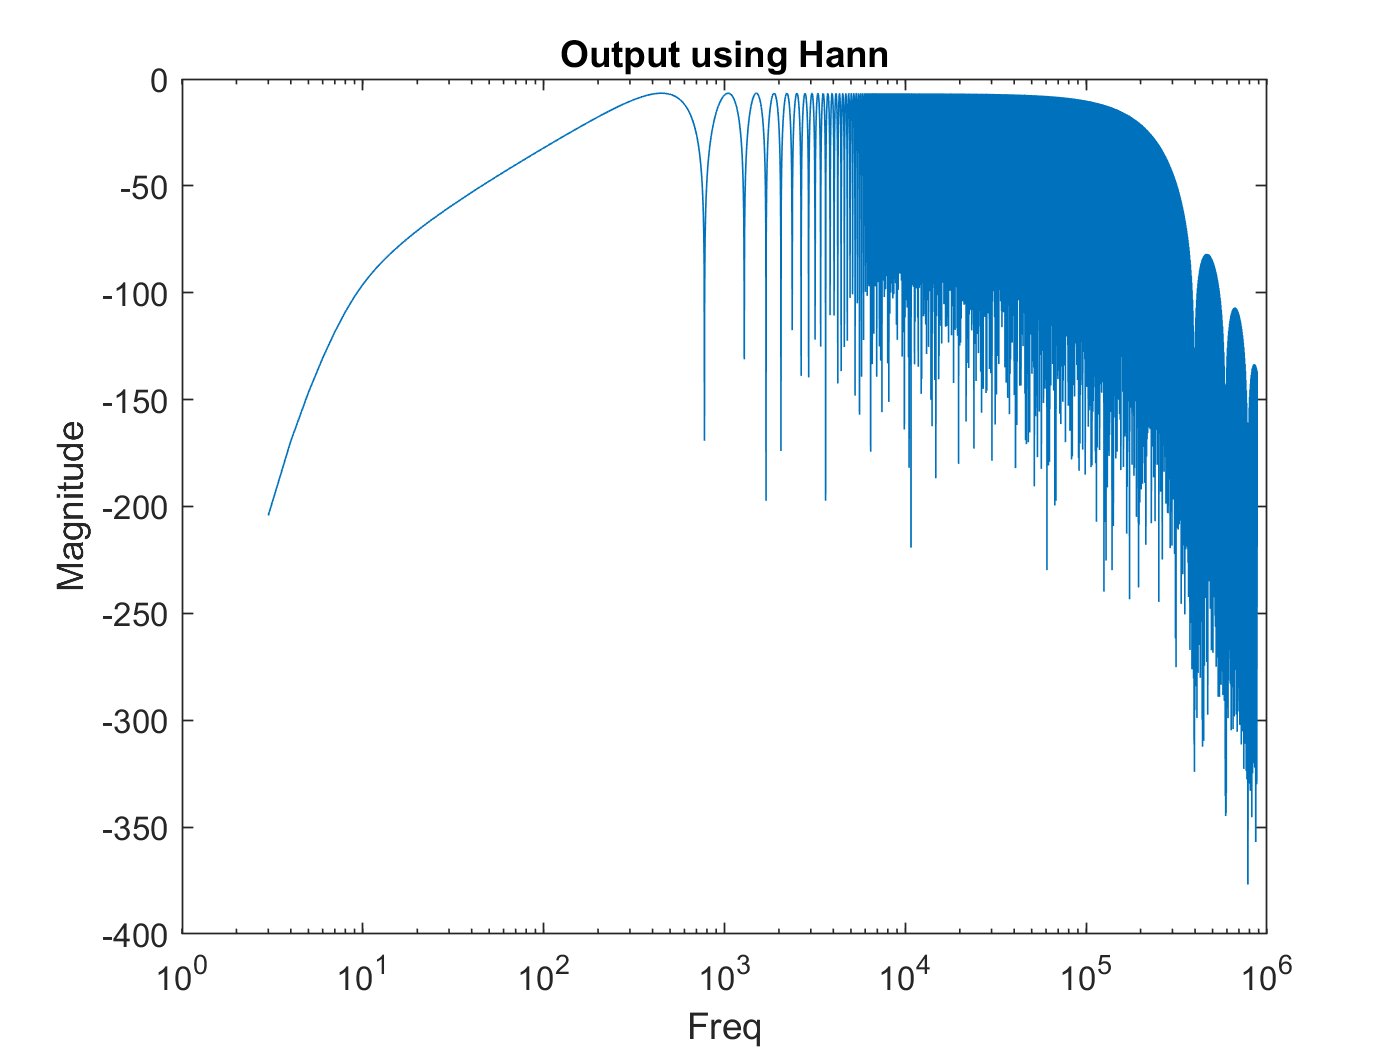

fir(B_Hann,"Hann")

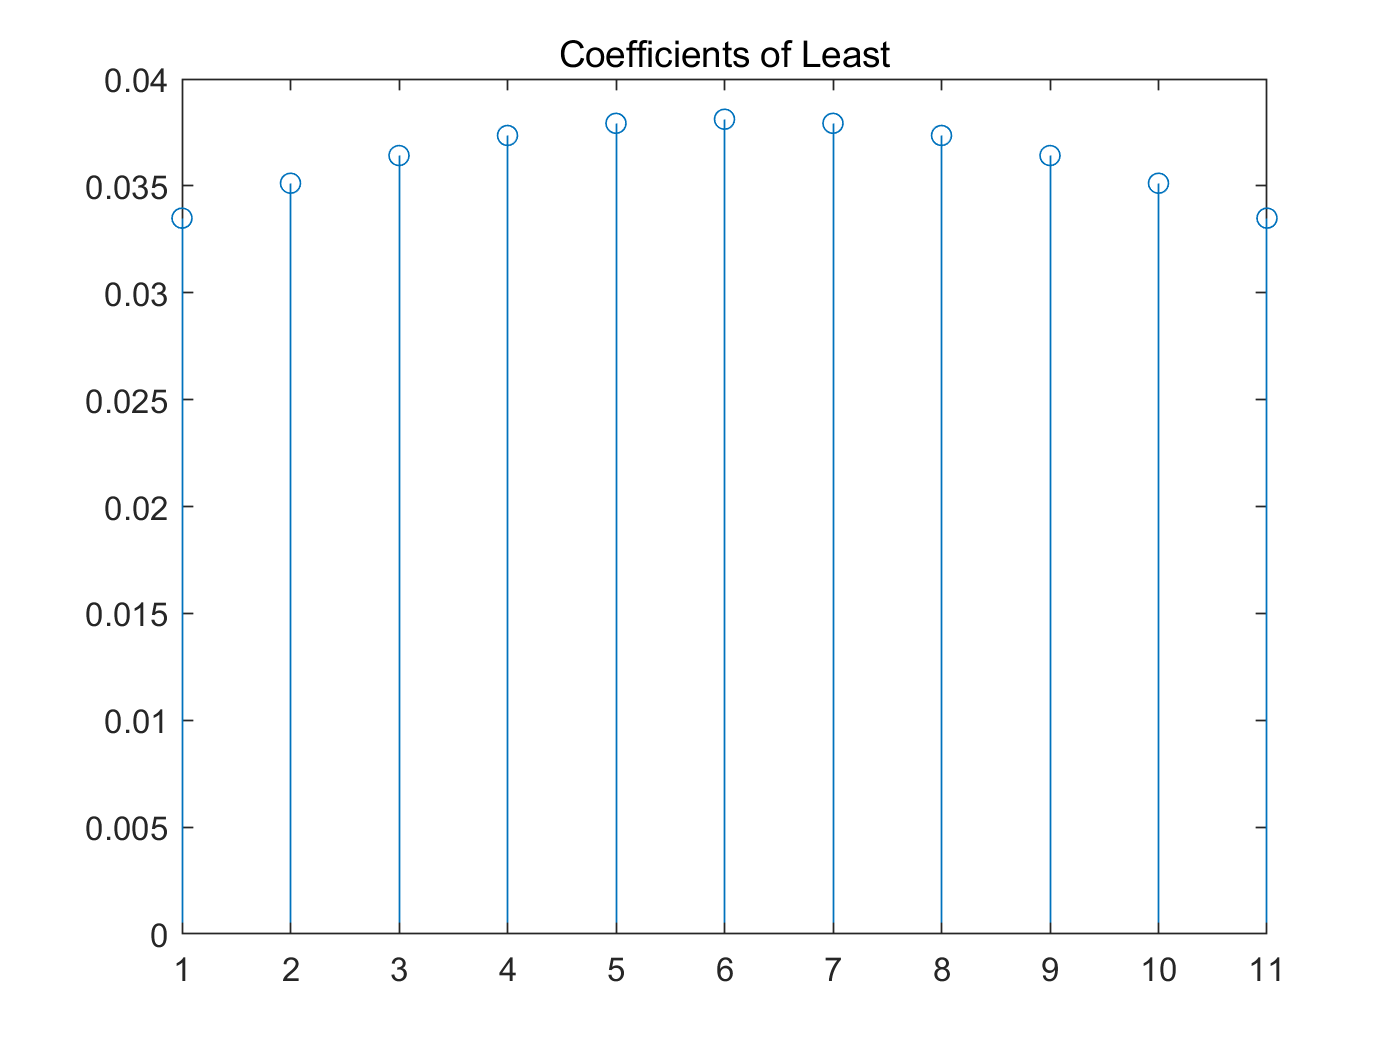

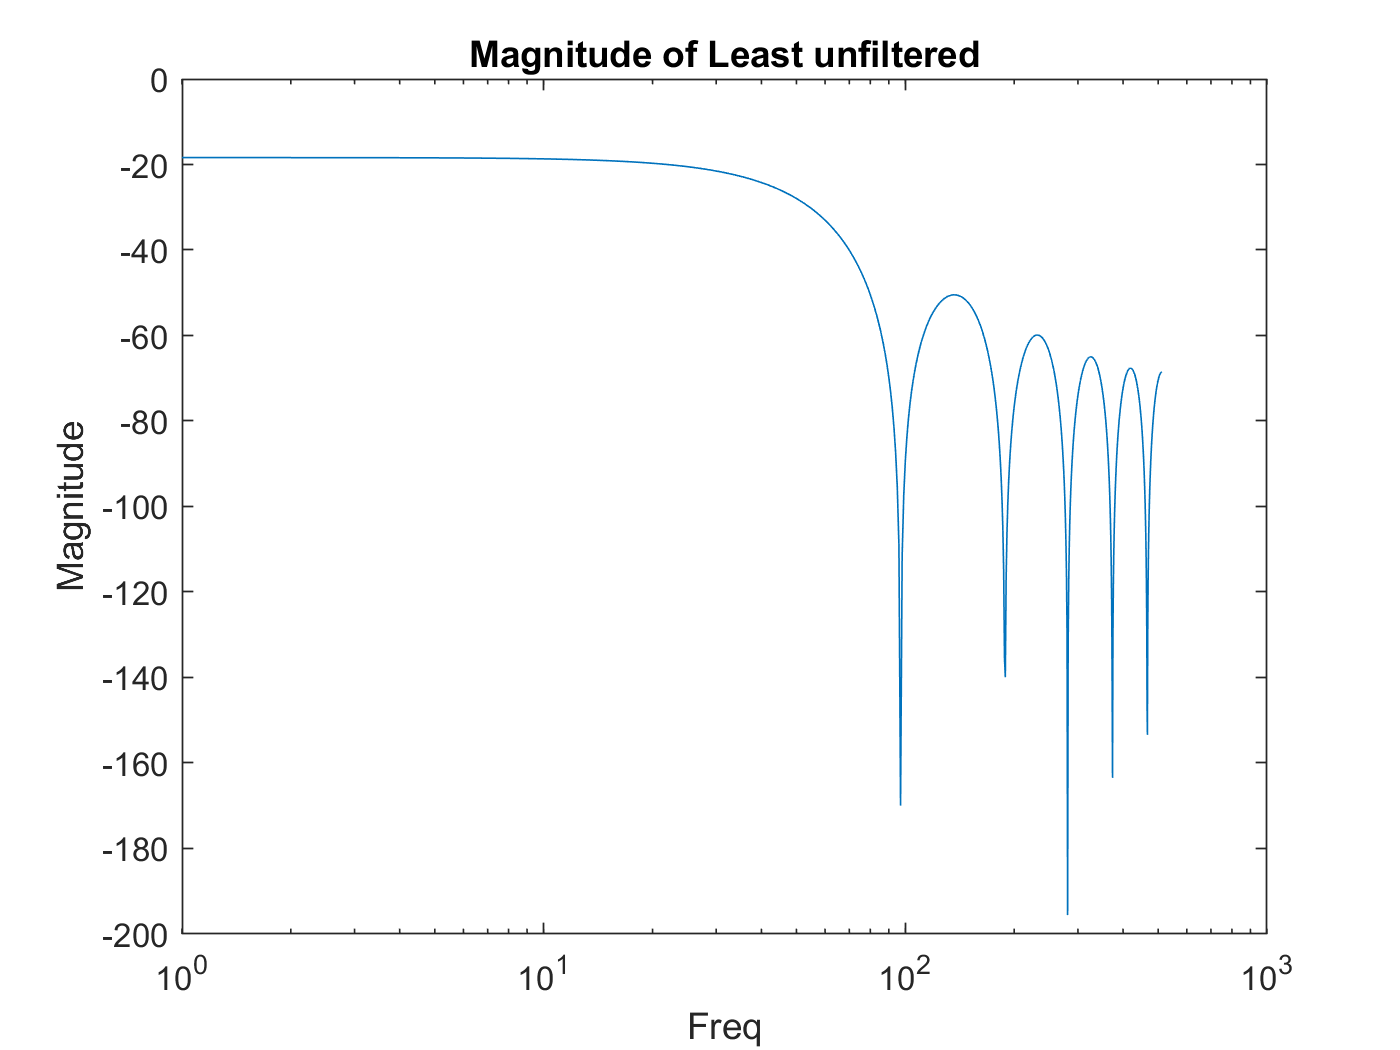

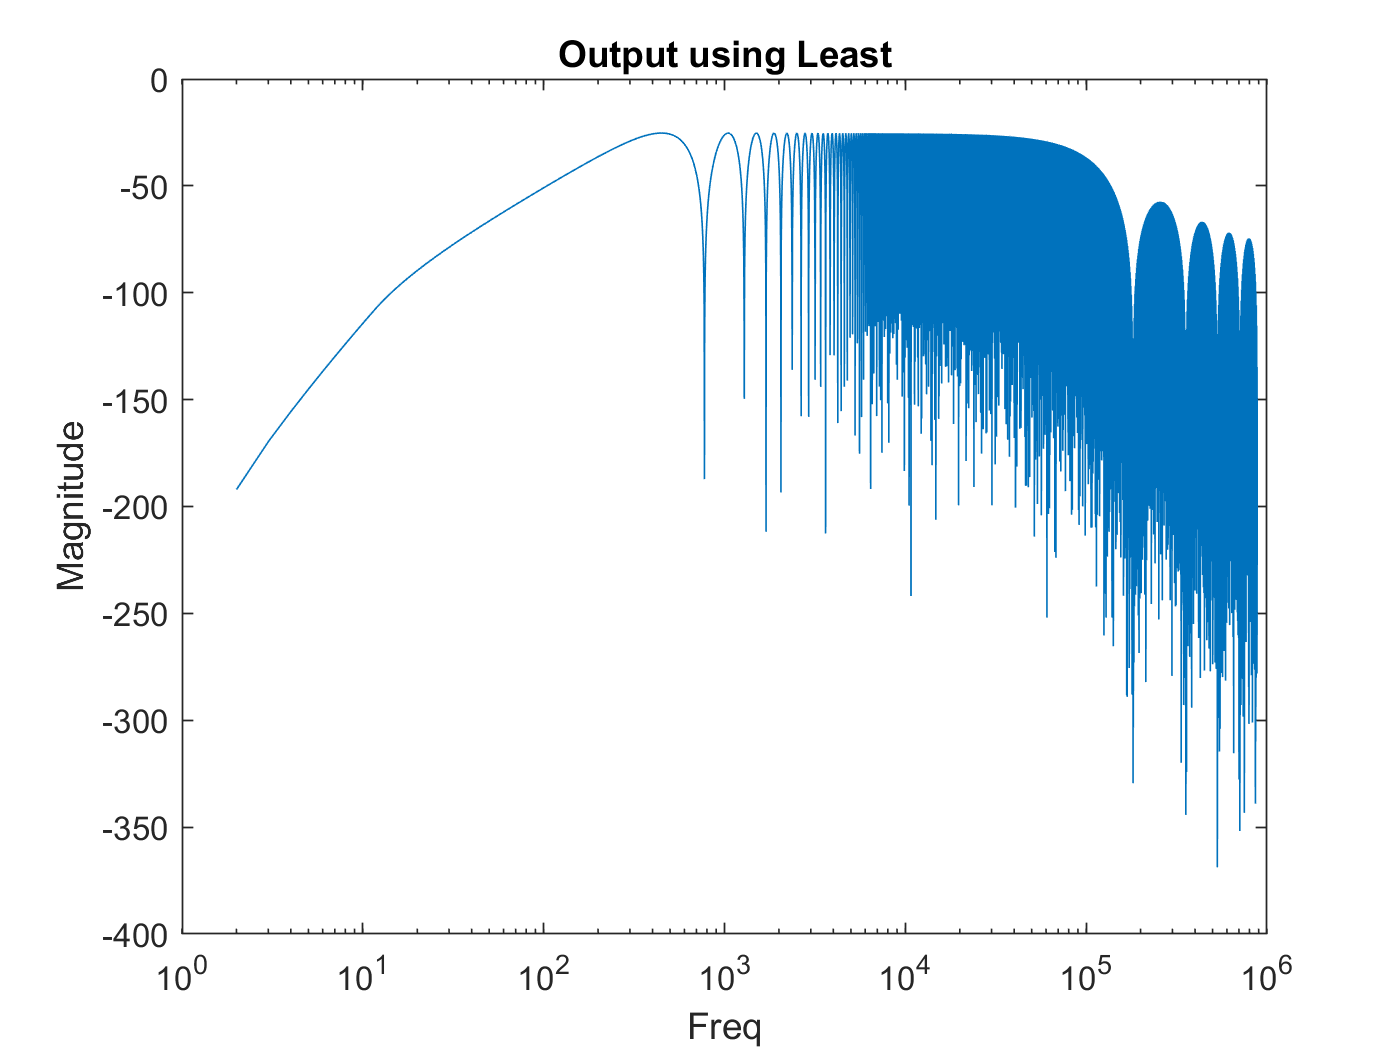

fir(Least,"Least")

Filters = {'Butterworth'; ' Chebychev Type II'; 'Elliptical'; 'Rectangle'; 'Hann'; 'Least Squarred'};
StopBandRipple = [0; 0; 0; 0; 0; 0];
PassBandRipple = [0; 0; 0; 0; 0; 0];
TransmitionBandwidth = [0; 0; 0; 0; 0; 0];
PassBandGain = [0; 0; 0; 0; 0; 0];
StopBandGain = [0; 0; 0; 0; 0; 0];
NumberCoeff =[0; 0; 0; 0; 0; 0];
T = table(Filters, StopBandRipple,PassBandRipple,TransmitionBandwidth, PassBandGain,StopBandGain,NumberCoeff)

T = 6×7 table
           Filters            StopBandRipple    PassBandRipple    TransmitionBandwidth    PassBandGain    StopBandGain    NumberCoeff
    ______________________    ______________    ______________    ____________________    ____________    ____________    ___________

    {'Butterworth'       }          0                 0                    0                   0               0               0     
    {' Chebychev Type II'}          0                 0                    0                   0               0               0     
    {'Elliptical'        }          0                 0                    0                   0               0               0     
    {'Rectangle'         }          0                 0                    0 

function i = iir(x,y,audio)
[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");

[B, A] = sos2tf(x, y);
figure();
semilogx(log(abs(x_log).^20)); %db y scale
subtitle("Magnitude of "  + audio + " unfiltered")
ylabel('Magnitude')
xlabel("Freq Log")
figure()
stem(B)
hold on
stem(A)
subtitle("Coefficients of " + audio)
legend('B','A')

y = filtfilt(x,y,x_log);
[h,w]=freqz(B,A);
figure()
semilogx(log(abs(h).^20));
ylabel('Magnitude (db)');
xlabel('Freq (Hz)');
subtitle('Magnitude Response of ' + audio);
%sgtitle('Testing')

audiowrite(audio + '.wav',y,fs_log)

end

function f = fir(x,audio)
[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");

figure()
stem(x)
subtitle('Coefficients of ' + audio)

figure()
[h,w] = freqz(x,1);
semilogx(log(abs(h).^20));
title('Magnitude of ' + audio + " unfiltered")
ylabel('Magnitude')
xlabel('Freq')

y=filter(x,1,x_lin);
figure()
semilogx(log(abs(y).^20));
title('Output using ' + audio)
ylabel('Magnitude')
xlabel('Freq')

audiowrite(audio + '.wav',y,fs_lin)

end